# Path Planning for Drone

Move 4 ft x 4 ft drone using RRT Planner

Load map of house 

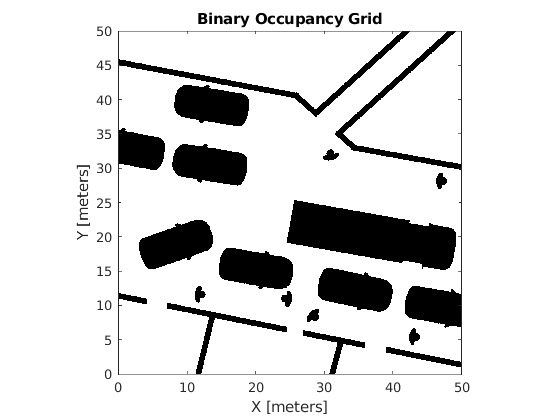

clear all
close all

% load image and create Occupancy map from image
grid = loadMap('city_map.png', 50);
show(grid)

Create costmap using vehicleCostmap function from toolbox

costmap = vehicleCostmap(grid)

costmap =   vehicleCostmap with properties:

        FreeThreshold: 0.2000
    OccupiedThreshold: 0.6500
     CollisionChecker: [1×1 driving.costmap.InflationCollisionChecker]
             CellSize: 0.0333
              MapSize: [1500 1500]
            MapExtent: [0 50 0 50]


Modify dimensions of drone and parameters of collision checker.  Drone is 0.5 m x 0.5 m.  

One circle of radius 0.5 m at the center of the drone will be used to check for collisions.

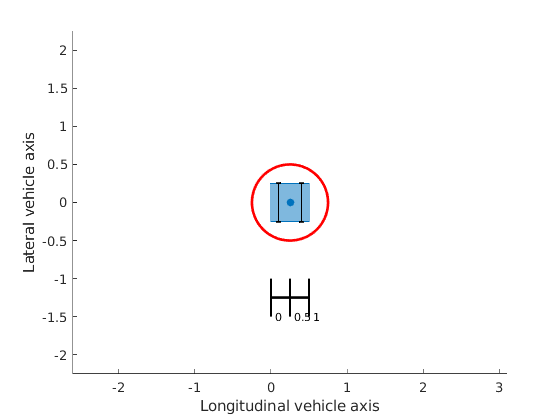


UAVdims = vehicleDimensions(0.5,0.5, 'FrontOverhang',0.1,'RearOverhang',0.1); 
numCircles = 1;
inflationRadius = 0.5;
ccConfig = inflationCollisionChecker(UAVdims, numCircles,'InflationRadius',inflationRadius);
plot(ccConfig)

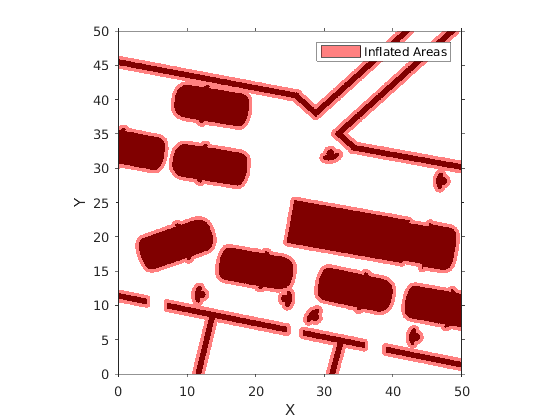


costmap.CollisionChecker = ccConfig;

figure
plot(costmap)

Run the path planner and plot on the map

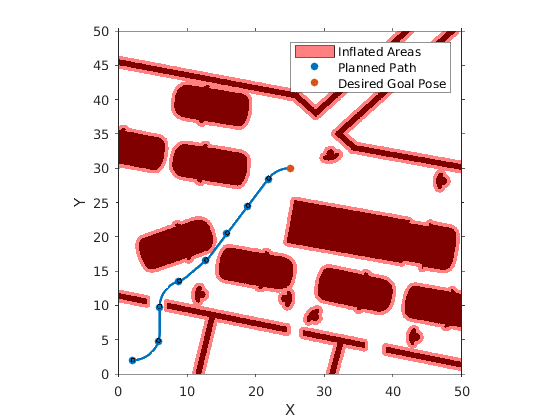

%Set the start and goal states.
start = [2,2,0];
goal = [25,30,0];

planner = pathPlannerRRT(costmap);
refPath = plan(planner,start,goal);

plot(planner)
hold on